# Modifying Squishy Data Processing

Things we want to include:

- one matrix for all our data

- should combine with CaSO4_mixing file

- make this one big function file

Chopping off the outlier data

% good_rows = 1:18000;
% conductivity_list = conductivity_list(good_rows,:);
% permeate_flowrate_list = permeate_flowrate_list(good_rows,:);
% flowrate_list = flowrate_list(good_rows,:);
% time_list = time_list(good_rows,:);
% batch_flow_rate = time_list(good_rows,:);
time_list_hour = time_list/3600;

a/ Calculating salt rejection  = [1-(permeate conductivity)/(average conductivity on feed side of membrane)]

perm_conductivity = 0.4; % mS/c - it's ok to guess
salt_rej = (1-(perm_conductivity)./mean(conductivity_list))*100 % percentage

salt_rej = 92.3797

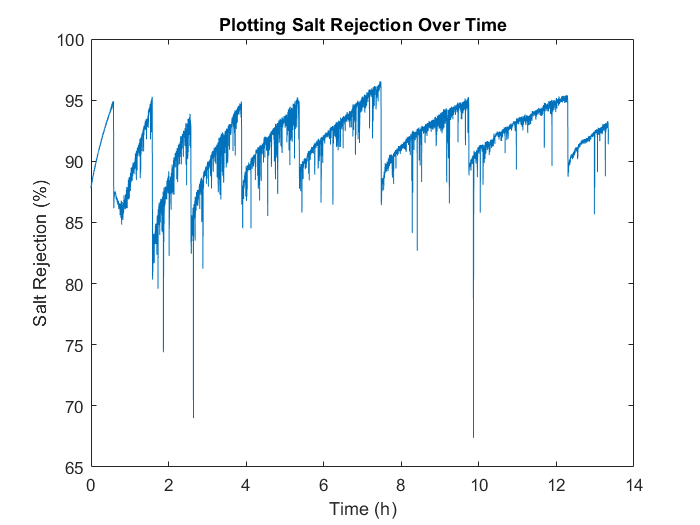

salt_rej_list = (1-(perm_conductivity)./(conductivity_list))*100;

plot(time_list_hour,salt_rej_list)
title('Plotting Salt Rejection Over Time')
xlabel('Time (h)')
ylabel('Salt Rejection (%)')

b/ Calculate the calcium sulfate concentration at the membrane at each timestep (from input initial concentration and instantaneous recovery and including concentration polarization.)

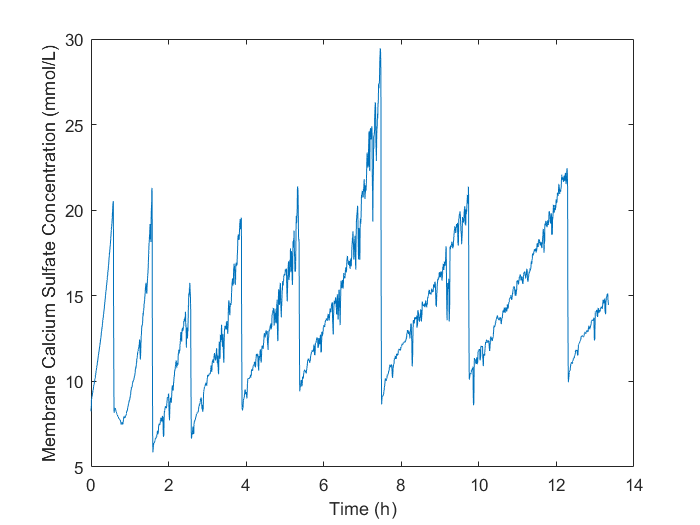

t_min_av = 0.5;         % minutes to average over
t_interval = 1;          % NOTE: data time interval is approximate
n_av = t_min_av * 60/t_interval;

recovery_rate = (1-(initial_conductivity./conductivity_list))*100; % Recovery Rate (%)
initial_conc = 4.6; % mg/mol
mem_CaSO4_conc = (1./(1-(recovery_rate./100))) .* initial_conc;     % membrane CaSO4 concentration
mem_CaSO4_conc_avg = movmean(mem_CaSO4_conc,n_av);

%plotting Membrane Calcium Sulfate Concentration
plot(time_list/3600,mem_CaSO4_conc_avg)
%title('Membrane Calcium Sulfate Concentration Over Time')
xlabel('Time (h)')
ylabel('Membrane Calcium Sulfate Concentration (mmol/L)')

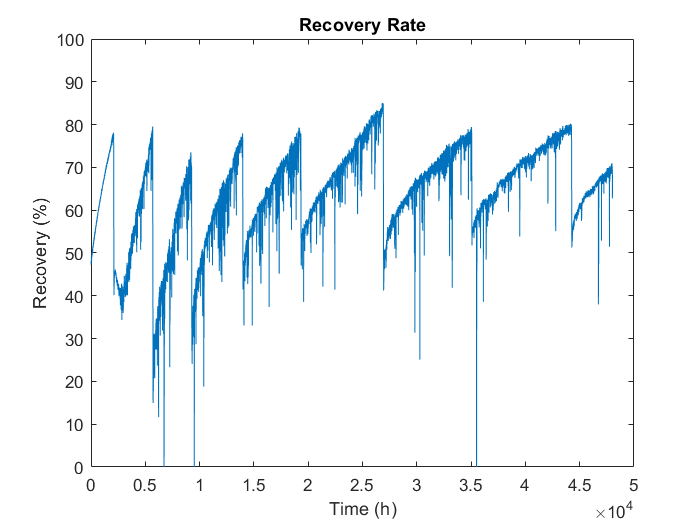


% plotting Recovery Rate over time
plot(time_list,recovery_rate)
title('Recovery Rate')
xlabel('Time (h)')
ylabel('Recovery (%)')
ylim([-0 100])

c/ Calculate the saturation index of gypsum (a.k.a. calcium sulfate dihydrate) at the membrane at each timestep.

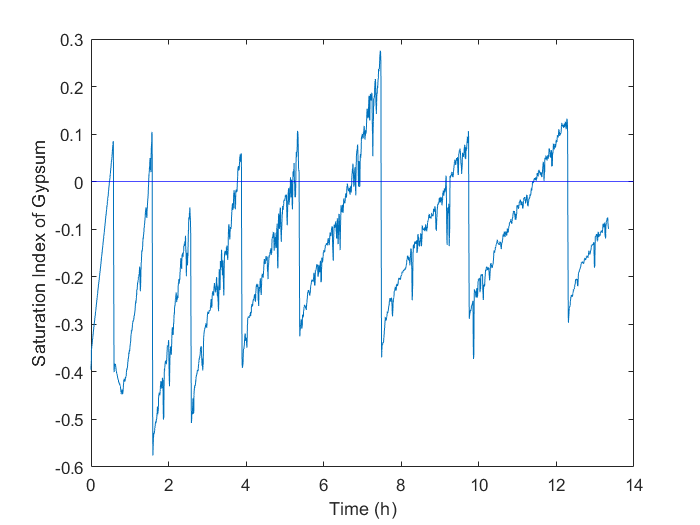

% equation in comments of doc
sat_index = 0.527 .* log(mem_CaSO4_conc_avg) - 1.5073;

% plotting Saturation Gypsum over time

plot(time_list_hour,sat_index)
%title('Saturation Index of Gypsum Over Time')
xlabel('Time (h)')
ylabel('Saturation Index of Gypsum')
yline(0,'b-')

d/ Calculate the nucleation induction time of gypsum at each timestep.

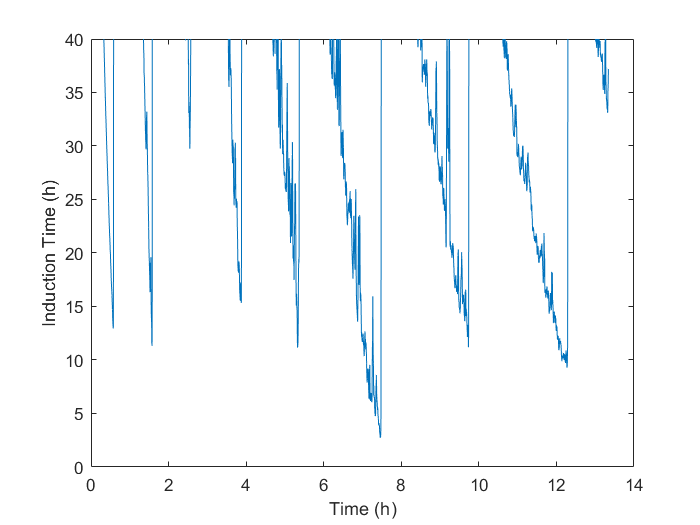

ind_time = 1.66*(10^6).*(exp(-0.174.*mem_CaSO4_conc_avg)); % Induction Time in seconds (s)
inv_ind_time = 1./ind_time;


plot(time_list_hour,ind_time/3600)
%title('Induction Time over Time')
xlabel('Time (h)')
ylabel('Induction Time (h)')
ylim([0,40])

e/ Integrate the induction rate (i.e., the inverse of induction time) over all timesteps in each batch cycle to determine the nucleation probability per cycle

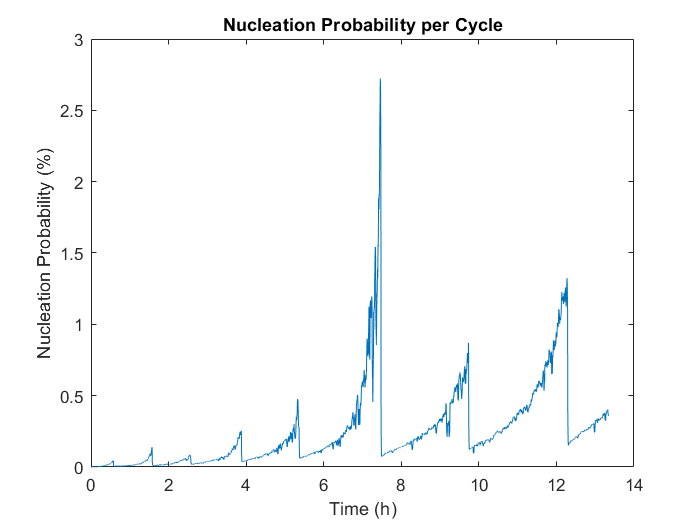

nucl_prob = (inv_ind_time .* time_list);

plot(time_list_hour,nucl_prob)
title('Nucleation Probability per Cycle')
xlabel('Time (h)')
ylabel('Nucleation Probability (%)')